# Train Generative Adversarial Network (GAN) for Sound Synthesis

This example shows how to train and use a generative adversarial network (GAN) to generate sounds.

Note: for the following exercise, please turn the speakers on.

Some of the functions used in this livescript require the Signal Processing Toolbox™ or the Matlab Audio Toolbox™. If these support packages are not installed, the functions provide the download links.

% Clear workspace and command window
clear;
clc;

## Introduction

A GAN is a type of deep learning network that generates data with characteristics similar to the training data. A GAN consists of two networks that train together, a *generator* and a *discriminator*:

- Generator - Given a vector or random values as input, this network generates data with the same structure as the training data. It is the generator's job to fool the discriminator.

- Discriminator - Given batches of data containing observations from both the training data and the generated data, this network attempts to classify the observations as real or generated.

This example trains a GAN for unsupervised synthesis of audio waveforms. The GAN in this example generates drumbeat sounds. The same approach can be followed to generate other types of sound, including speech.

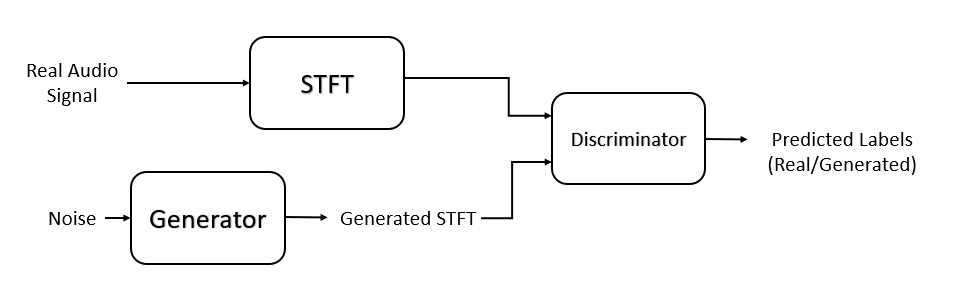

### Load Training Data

Train a GAN using the Drum Sound Effects dataset [2]. The script `downloadDrumSoundEffectsDataset will` download and extract the dataset in the current folder.

The dataset is composed of about 3000 audio tracks (0.7 hours in total) reproducing drum samples for kicks, snares, toms, and cymbals. The dataset is already split into train, validation, and test set by the authors. 

downloadDrumSoundEffectsDataset;

Create an [`audioDatastore`](https://it.mathworks.com/help/audio/ref/audiodatastore.html) object that points to the drums dataset.

ads = audioDatastore(drumsFolder,'IncludeSubfolders',true);

### Define Generator Network

Define a network that generates STFTs from 1-by-1-by-100 arrays of random values. Create a network that upscales 1-by-1-by-100 arrays to 128-by-128-by-1 arrays using a [fully connected layer](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.fullyconnectedlayer.html) followed by a reshape layer and a series of [transposed convolution layers](https://it.mathworks.com/help/deeplearning/ref/transposedconv2dlayer.html) with [ReLU layers](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.relulayer.html).

This figure shows the dimensions of the signal as it travels through the generator. The generator architecture is defined in Table 4 of [1].

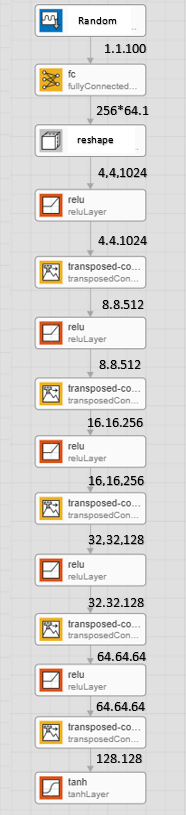

The generator network is defined in modelGenerator, which is included at the end of this example.

### Define Discriminator Network

Define a network that classifies real and generated 128-by-128 STFTs.

Create a network that takes 128-by-128 images and outputs a scalar prediction score using a series of convolution layers with [leaky ReLU layers](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.leakyrelulayer.html) followed by a fully connected layer.

This figure shows the dimensions of the signal as it travels through the discriminator. The discriminator architecture is defined in Table 5 of [1].

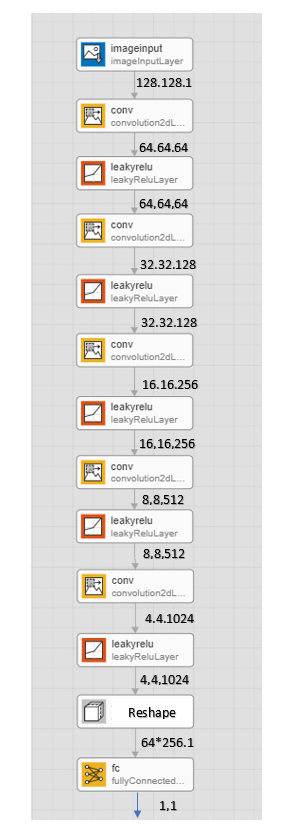

The discriminator network is defined in modelDiscriminator, which is included at the end of this example.

### Generate Real Drumbeat Training Data

Generate STFT data from the drumbeat signals in the datastore.

To speed up processing, distribute the feature extraction across multiple workers using [`parfor`](https://it.mathworks.com/help/parallel-computing/parfor.html).

% Determine the number of partitions for the dataset. If you do not have Parallel Computing Toolbox™, use a single partition
if ~isempty(ver('parallel'))
    pool = gcp;
    numPar = numpartitions(ads,pool);
else
    numPar = 1;
end

% Define the SIFT parameters
fftLength = 256;
win = hann(fftLength,'periodic');
overlapLength = 128;

% Compute the SIFT of each partition
parfor ii = 1:numPar

    subds = partition(ads,numPar,ii);
    STrain = zeros(fftLength/2+1,128,1,numel(subds.Files));
    
    for idx = 1:numel(subds.Files)
        
        x = read(subds);
        
        if length(x) > fftLength*64 
            % Lengthen the signal if it is too short
            x = x(1:fftLength*64);
        end
        
        % Convert from double-precision to single-precision
        x = single(x);
        
        % Scale the signal
        x = x ./ max(abs(x));
        
        % Zero-pad to ensure stft returns 128 windows.
        x = [x ; zeros(overlapLength,1,'like',x)];
        
        S0 = stft(x,'Window',win,'OverlapLength',overlapLength,'Centered',false);
        
        % Convert from two-sided to one-sided.
        S = S0(1:129,:);
        S = abs(S);
        STrain(:,:,:,idx) = S;
    end
    STrainC{ii} = STrain;
end

Some post-processing on the extracted features are needed in order to help the GAN training.

The data are converted to the log scale to better align with human perception and each frequency bin is normalized and clipped in order to discard high variation that could disturb the GAN weight updating during the training process.

% Convert the output to a four-dimensional array with STFTs along the fourth dimension
STrain = cat(4,STrainC{:});

% Convert the data to the log scale to better align with human perception
STrain = log(STrain + 1e-6);

% Compute the STFT mean and standard deviation of each frequency bin
SMean = mean(STrain,[2 3 4]);
SStd = std(STrain,1,[2 3 4]);

% Normalize each frequency bin
STrain = (STrain-SMean)./SStd;

%  Make the data bounded by clipping the spectra to 3 standard deviations and rescaling to [-1 1]
STrain = STrain/3;
Y = reshape(STrain,numel(STrain),1);
Y(Y<-1) = -1;
Y(Y>1) = 1;
STrain = reshape(Y,size(STrain));

% Discard the last frequency bin to force the number of STFT bins to a power of two 
% (which works well with convolutional layers)
STrain = STrain(1:end-1,:,:,:);
% Permute the dimensions in preparation for feeding to the discriminator
STrain = permute(STrain,[2 1 3 4]);

### Specify Training Options

Following we specify the training options for the GAN training. 

We train with a mini-batch size of 64 (decrease to 32 if it does not fit in your GPU memory) for 1000 epochs.

Train on a GPU if one is available. Using a GPU requires Parallel Computing Toolbox™.

maxEpochs = 1000;
miniBatchSize = 64;

numIterationsPerEpoch = floor(size(STrain,4)/miniBatchSize); % number of iterations required to consume the data (ie. for each epoch)

% Adam optimizer options
learnRateGenerator = 0.0002;
learnRateDiscriminator = 0.0002;
gradientDecayFactor = 0.5;
squaredGradientDecayFactor = 0.999;

executionEnvironment = "auto"; % Train on a GPU if one is available.

### Inizialize the Network Weights

Initialize the generator and discriminator weights. The `initializeGeneratorWeights` and `initializeDiscriminatorWeights` functions return random weights obtained using Glorot uniform initialization. The functions are included at the end of this example.

generatorParameters = initializeGeneratorWeights;
discriminatorParameters = initializeDiscriminatorWeights;

### Train Model

In this example we will train the model using a custom training loop. We loop over the training data and update the network parameters at each iteration. 

For each epoch, shuffle the training data and loop over mini-batches of data.

For each mini-batch:

- Generate a [dlarray](https://it.mathworks.com/help/deeplearning/ref/dlarray.html) object containing an array of random values for the generator network.

- For GPU training, convert the data to a [`gpuArray`](https://it.mathworks.com/help/parallel-computing/gpuarray.html) object.

- Evaluate the model gradients using [`dlfeval`](https://it.mathworks.com/help/deeplearning/ref/dlfeval.html) and the helper functions, `modelDiscriminatorGradients` and `modelGeneratorGradients`.

- Update the network parameters using the [`adamupdate`](https://www.mathworks.com/help/deeplearning/ref/adamupdate.html) function.

Initialize the parameters for Adam.

trailingAvgGenerator = [];
trailingAvgSqGenerator = [];
trailingAvgDiscriminator = [];
trailingAvgSqDiscriminator = [];

You can set `saveCheckpoints` to `true` to save the updated weights and states to a MAT file every ten epochs. You can then use this MAT file to resume training if it is interrupted. For the purpose of this example, set `saveCheckpoints` to `false`.

saveCheckpoints = false;

Specify the length of the generator input.

numLatentInputs = 100;
saveEpochs = 10; % Save the checkpoints every 10 epochs

Train the GAN. This can take multiple hours to run. If you don’t want to train the network, set `doTrain` to `false` and run the section.

iteration = 0;
doTrain = false; % Specify if perform the training process

if doTrain

    for epoch = 1:maxEpochs
    
        % Shuffle the data.
        idx = randperm(size(STrain,4));
        STrain = STrain(:,:,:,idx);
    
        % Loop over mini-batches.
        for index = 1:numIterationsPerEpoch
            
            iteration = iteration + 1;
    
            % Read mini-batch of data.
            dlX = STrain(:,:,:,(index-1)*miniBatchSize+1:index*miniBatchSize);
            dlX = dlarray(dlX,'SSCB');
            
            % Generate latent inputs for the generator network.
            Z = 2 * ( rand(1,1,numLatentInputs,miniBatchSize,'single') - 0.5 ) ;
            dlZ = dlarray(Z);
    
            % If training on a GPU, then convert data to gpuArray.
            if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
                dlZ = gpuArray(dlZ);
                dlX = gpuArray(dlX);
            end
            
            % Evaluate the discriminator gradients using dlfeval and the
            % |modelDiscriminatorGradients| helper function.
            gradientsDiscriminator = ...
                dlfeval(@modelDiscriminatorGradients,discriminatorParameters,generatorParameters,dlX,dlZ);
            
            % Update the discriminator network parameters.
            [discriminatorParameters,trailingAvgDiscriminator,trailingAvgSqDiscriminator] = ...
                adamupdate(discriminatorParameters,gradientsDiscriminator, ...
                trailingAvgDiscriminator,trailingAvgSqDiscriminator,iteration, ...
                learnRateDiscriminator,gradientDecayFactor,squaredGradientDecayFactor);
    
            % Generate latent inputs for the generator network.
            Z = 2 * ( rand(1,1,numLatentInputs,miniBatchSize,'single') - 0.5 ) ;
            dlZ = dlarray(Z);
            
            % If training on a GPU, then convert data to gpuArray.
            if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
                dlZ = gpuArray(dlZ);
            end
            
            % Evaluate the generator gradients using dlfeval and the
            % |modelGeneratorGradients| helper function.
            gradientsGenerator  = ...
                dlfeval(@modelGeneratorGradients,discriminatorParameters,generatorParameters,dlZ);
            
            % Update the generator network parameters.
            [generatorParameters,trailingAvgGenerator,trailingAvgSqGenerator] = ...
                adamupdate(generatorParameters,gradientsGenerator, ...
                trailingAvgGenerator,trailingAvgSqGenerator,iteration, ...
                learnRateGenerator,gradientDecayFactor,squaredGradientDecayFactor);
        end
     
        % Every saveEpochs iterations, save a training snapshot to a MAT file.
        if saveCheckpoints && mod(epoch,saveEpochs)==0
            fprintf('Epoch %d out of %d complete\n',epoch,maxEpochs);
            % Save checkpoint in case training is interrupted.
            save('audiogancheckpoint.mat',...
                'generatorParameters','discriminatorParameters',...
                'trailingAvgDiscriminator','trailingAvgSqDiscriminator',...
                'trailingAvgGenerator','trailingAvgSqGenerator','iteration','SMean','SStd');
        end
    end

end

## Synthesize Audio with Pre-Trained GAN

Now that you have trained the network, you can investigate the synthesis process in more detail.

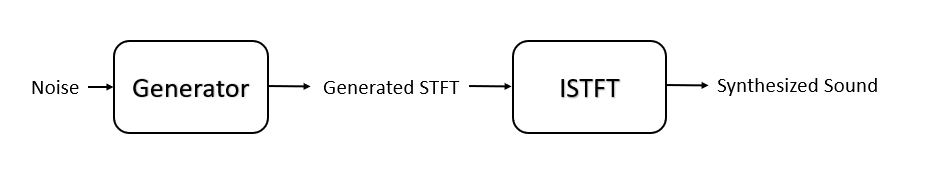

The trained drumbeat generator synthesizes short-time Fourier transform (STFT) matrices from input arrays of random values. An inverse STFT (ISTFT) operation converts the time-frequency STFT to a synthesized time-domain audio signal.

### Load pre-trained weights

Load the weights of a pretrained generator. These weights were obtained by running the training highlighted in the previous section for 1000 epochs. Note that it might take a couple of minutes.

didTrain = doTrain; % If you performed the training in the previous section

if didTrain
    matFileName = 'audiogancheckpoint.mat';
else
    matFileName = 'drumGeneratorWeights.mat';
    if ~exist(matFileName,'file')
        websave(matFileName,'https://www.mathworks.com/supportfiles/audio/GanAudioSynthesis/drumGeneratorWeights.mat');
    end
end

load(matFileName,'generatorParameters','SMean','SStd');

### Generate the drum sample

The generator takes 1-by-1-by-100 vectors of random values as an input. Generate a sample input vector.

numLatentInputs = 100;
dlZ = dlarray(2 * ( rand(1,1,numLatentInputs,1,'single') - 0.5 ));

Pass the random vector to the generator to create an STFT image. `generatorParameters` is a structure containing the weights of the pretrained generator.

dlXGenerated = modelGenerator(dlZ,generatorParameters);

### Post-process the generated STFT image

Perform different post-processing operations to the generated STFT image in order to produce the audio samples.

S = dlXGenerated.extractdata; % Convert the STFT dlarray to a single-precision matrix
S = S.'; % Transpose the STFT to align its dimensions with the istft function

The STFT is a 128-by-128 matrix, where the first dimension represents 128 frequency bins linearly spaced from 0 to 8 kHz. The generator was trained to generate a one-sided STFT from an FFT length of 256, with the last bin omitted. Reintroduce that bin by inserting a row of zeros into the STFT.

S = [S ; zeros(1,128)];

Revert the normalization and scaling steps used when you generated the STFTs for training.

S = S * 3;
S = (S.*SStd) + SMean;

% Convert the STFT from the log domain to the linear domain
S = exp(S);

% Convert the STFT from one-sided to two-sided
S = [S; S(end-1:-1:2,:)];

% Pad with zeros to remove window edge-effects
S = [zeros(256,100) S zeros(256,100)];

The STFT matrix does not contain any phase information but only the magnitude. For this reason we cannot convert directly the STFT to time-domain signal.

We use the function [stftmag2sig](https://it.mathworks.com/help/signal/ref/stftmag2sig.html)  that reconstructs the signal from the STFT magnitude. Here a fast version of the Griffin-Lim algorithm with 20 iterations is used to estimate the signal phase and produce audio samples.

myAudio = stftmag2sig(S,256, ...
    'FrequencyRange','twosided', ...
    'Window',hann(256,'periodic'), ...
    'OverlapLength',128, ...
    'MaxIterations',20, ...
    'Method','fgla');
myAudio = myAudio./max(abs(myAudio),[],'all');
myAudio = myAudio(128*100:end-128*100);

### Listen and Visualize the Synthesized drumbeat

Listen to and visualize the synthesized drumbeat.

fs = 16e3;
sound(myAudio,fs);

% Plot the synthesized drumbeat
t = (0:length(myAudio)-1)/fs;
plot(t,myAudio)
grid on
xlabel('Time (s)')
title('Synthesized GAN Sound')

% Plot the STFT of the synthesized drumbeat
figure
stft(myAudio,fs,'Window',hann(256,'periodic'),'OverlapLength',128);

## Reference

[1] Donahue, C., J. McAuley, and M. Puckette. 2019. "Adversarial Audio Synthesis." ICLR.

[2] Drum sound effects dataset: http://deepyeti.ucsd.edu/cdonahue/wavegan/data/drums.tar.gz

## Further readings

[Generative Adversarial Networks](https://it.mathworks.com/discovery/generative-adversarial-networks.html)

[Train Generative Adversarial Network for Images Generation](https://it.mathworks.com/help/deeplearning/ug/train-generative-adversarial-network.html)

[Monitor GAN Training Progress and Identify Common Failure Modes](https://it.mathworks.com/help/deeplearning/ug/monitor-gan-training-progress-and-identify-common-failure-modes.html)

## Helper functions

Some function that are useful for network definition and training.

### Model Generator Function

The `modelGenerator` function upscales 1-by-1-by-100 arrays (dlX) to 128-by-128-by-1 arrays (dlY). `parameters` is a structure holding the weights of the generator layers. The generator architecture is defined in Table 4 of [1].

function dlY = modelGenerator(dlX,parameters)

dlY = fullyconnect(dlX,parameters.FC.Weights,parameters.FC.Bias,'Dataformat','SSCB');

dlY = reshape(dlY,[1024 4 4 size(dlY,2)]);
dlY = permute(dlY,[3 2 1 4]);
dlY = relu(dlY);

dlY = dltranspconv(dlY,parameters.Conv1.Weights,parameters.Conv1.Bias,'Stride' ,2 ,'Cropping','same','DataFormat','SSCB');
dlY = relu(dlY);

dlY = dltranspconv(dlY,parameters.Conv2.Weights,parameters.Conv2.Bias,'Stride' ,2 ,'Cropping','same','DataFormat','SSCB');
dlY = relu(dlY);

dlY = dltranspconv(dlY,parameters.Conv3.Weights,parameters.Conv3.Bias,'Stride' ,2 ,'Cropping','same','DataFormat','SSCB');
dlY = relu(dlY);

dlY = dltranspconv(dlY,parameters.Conv4.Weights,parameters.Conv4.Bias,'Stride' ,2 ,'Cropping','same','DataFormat','SSCB');
dlY = relu(dlY);

dlY = dltranspconv(dlY,parameters.Conv5.Weights,parameters.Conv5.Bias,'Stride' ,2 ,'Cropping','same','DataFormat','SSCB');
dlY = tanh(dlY);
end

### Model Discriminator Function

The `modelDiscriminator` function takes 128-by-128 images and outputs a scalar prediction score. The discriminator architecture is defined in Table 5 of [1].

function dlY = modelDiscriminator(dlX,parameters)

dlY = dlconv(dlX,parameters.Conv1.Weights,parameters.Conv1.Bias,'Stride' ,2 ,'Padding','same');
dlY = leakyrelu(dlY,0.2);

dlY = dlconv(dlY,parameters.Conv2.Weights,parameters.Conv2.Bias,'Stride' ,2 ,'Padding','same');
dlY = leakyrelu(dlY,0.2);

dlY = dlconv(dlY,parameters.Conv3.Weights,parameters.Conv3.Bias,'Stride' ,2 ,'Padding','same');
dlY = leakyrelu(dlY,0.2);

dlY = dlconv(dlY,parameters.Conv4.Weights,parameters.Conv4.Bias,'Stride' ,2 ,'Padding','same');
dlY = leakyrelu(dlY,0.2);

dlY = dlconv(dlY,parameters.Conv5.Weights,parameters.Conv5.Bias,'Stride' ,2 ,'Padding','same');
dlY = leakyrelu(dlY,0.2);
 
dlY = stripdims(dlY);
dlY = permute(dlY,[3 2 1 4]);
dlY = reshape(dlY,4*4*64*16,numel(dlY)/(4*4*64*16));

weights = parameters.FC.Weights;
bias = parameters.FC.Bias;
dlY = fullyconnect(dlY,weights,bias,'Dataformat','CB');

end

### Model Discriminator Gradients Function

The `modelDiscriminatorGradients` functions takes as input the generator and discriminator parameters `generatorParameters` and `discriminatorParameters`, a mini-batch of input data `dlX`, and an array of random values `dlZ`, and returns the gradients of the discriminator loss with respect to the learnable parameters in the networks.

function gradientsDiscriminator = modelDiscriminatorGradients(discriminatorParameters , generatorParameters, dlX, dlZ)

% Calculate the predictions for real data with the discriminator network.
dlYPred = modelDiscriminator(dlX,discriminatorParameters);

% Calculate the predictions for generated data with the discriminator network.
dlXGenerated     = modelGenerator(dlZ,generatorParameters);
dlYPredGenerated = modelDiscriminator(dlarray(dlXGenerated,'SSCB'),discriminatorParameters);

% Calculate the GAN loss
lossDiscriminator = ganDiscriminatorLoss(dlYPred,dlYPredGenerated);

% For each network, calculate the gradients with respect to the loss.
gradientsDiscriminator = dlgradient(lossDiscriminator,discriminatorParameters);

end

### Model Generator Gradients Function

The `modelGeneratorGradients` function takes as input the discriminator and generator learnable parameters and an array of random values `dlZ`, and returns the gradients of the generator loss with respect to the learnable parameters in the networks.

function gradientsGenerator = modelGeneratorGradients(discriminatorParameters, generatorParameters , dlZ)

% Calculate the predictions for generated data with the discriminator network.
dlXGenerated = modelGenerator(dlZ,generatorParameters);
dlYPredGenerated = modelDiscriminator(dlarray(dlXGenerated,'SSCB'),discriminatorParameters);

% Calculate the GAN loss
lossGenerator = ganGeneratorLoss(dlYPredGenerated);

% For each network, calculate the gradients with respect to the loss.
gradientsGenerator = dlgradient(lossGenerator, generatorParameters);

end

### Discriminator Loss Function

The objective of the discriminator is to not be fooled by the generator. To maximize the probability that the discriminator successfully discriminates between the real and generated images, minimize the discriminator loss function. The loss function for the generator follows the DCGAN approach highlighted in [1].

function  lossDiscriminator = ganDiscriminatorLoss(dlYPred,dlYPredGenerated)

fake = dlarray(zeros(1,size(dlYPred,2)));
real = dlarray(ones(1,size(dlYPred,2)));

D_loss = mean(sigmoid_cross_entropy_with_logits(dlYPredGenerated,fake));
D_loss = D_loss + mean(sigmoid_cross_entropy_with_logits(dlYPred,real));
lossDiscriminator  = D_loss / 2;
end

### Generator Loss Function

The objective of the generator is to generate data that the discriminator classifies as "real". To maximize the probability that images from the generator are classified as real by the discriminator, minimize the generator loss function. The loss function for the generator follows the deep convolutional generative adverarial network (DCGAN) approach highlighted in [1].

function lossGenerator = ganGeneratorLoss(dlYPredGenerated)
real = dlarray(ones(1,size(dlYPredGenerated,2)));
lossGenerator = mean(sigmoid_cross_entropy_with_logits(dlYPredGenerated,real));
end

### Discriminator Weights Initializer

`initializeDiscriminatorWeights` initializes discriminator weights using the Glorot algorithm.

function discriminatorParameters = initializeDiscriminatorWeights

filterSize = [5 5];
dim = 64;

% Conv2D
weights = iGlorotInitialize([filterSize(1) filterSize(2) 1 dim]);
bias = zeros(1,1,dim,'single');
discriminatorParameters.Conv1.Weights = dlarray(weights);
discriminatorParameters.Conv1.Bias = dlarray(bias);

% Conv2D
weights = iGlorotInitialize([filterSize(1) filterSize(2) dim 2*dim]);
bias = zeros(1,1,2*dim,'single');
discriminatorParameters.Conv2.Weights = dlarray(weights);
discriminatorParameters.Conv2.Bias = dlarray(bias);

% Conv2D
weights = iGlorotInitialize([filterSize(1) filterSize(2) 2*dim 4*dim]);
bias = zeros(1,1,4*dim,'single');
discriminatorParameters.Conv3.Weights = dlarray(weights);
discriminatorParameters.Conv3.Bias = dlarray(bias);

% Conv2D
weights = iGlorotInitialize([filterSize(1) filterSize(2) 4*dim 8*dim]);
bias = zeros(1,1,8*dim,'single');
discriminatorParameters.Conv4.Weights = dlarray(weights);
discriminatorParameters.Conv4.Bias = dlarray(bias);

% Conv2D
weights = iGlorotInitialize([filterSize(1) filterSize(2) 8*dim 16*dim]);
bias = zeros(1,1,16*dim,'single');
discriminatorParameters.Conv5.Weights = dlarray(weights);
discriminatorParameters.Conv5.Bias = dlarray(bias);

% fully connected
weights = iGlorotInitialize([1,4 * 4 * dim * 16]);
bias = zeros(1,1,'single');
discriminatorParameters.FC.Weights = dlarray(weights);
discriminatorParameters.FC.Bias = dlarray(bias);
end

### Generator Weights Initializer

`initializeGeneratorWeights` initializes generator weights using the Glorot algorithm.

function generatorParameters = initializeGeneratorWeights

dim = 64;

% Dense 1
weights = iGlorotInitialize([dim*256,100]);
bias = zeros(dim*256,1,'single');
generatorParameters.FC.Weights = dlarray(weights);
generatorParameters.FC.Bias = dlarray(bias);

filterSize = [5 5];

% Trans Conv2D
weights = iGlorotInitialize([filterSize(1) filterSize(2) 8*dim 16*dim]);
bias = zeros(1,1,dim*8,'single');
generatorParameters.Conv1.Weights = dlarray(weights);
generatorParameters.Conv1.Bias = dlarray(bias);

% Trans Conv2D
weights = iGlorotInitialize([filterSize(1) filterSize(2) 4*dim 8*dim]);
bias = zeros(1,1,dim*4,'single');
generatorParameters.Conv2.Weights = dlarray(weights);
generatorParameters.Conv2.Bias = dlarray(bias);

% Trans Conv2D
weights = iGlorotInitialize([filterSize(1) filterSize(2) 2*dim 4*dim]);
bias = zeros(1,1,dim*2,'single');
generatorParameters.Conv3.Weights = dlarray(weights);
generatorParameters.Conv3.Bias = dlarray(bias);

% Trans Conv2D
weights = iGlorotInitialize([filterSize(1) filterSize(2) dim 2*dim]);
bias = zeros(1,1,dim,'single');
generatorParameters.Conv4.Weights = dlarray(weights);
generatorParameters.Conv4.Bias = dlarray(bias);

% Trans Conv2D
weights = iGlorotInitialize([filterSize(1) filterSize(2) 1 dim]);
bias = zeros(1,1,1,'single');
generatorParameters.Conv5.Weights = dlarray(weights);
generatorParameters.Conv5.Bias = dlarray(bias);
end

### Utility Function

function out = sigmoid_cross_entropy_with_logits(x,z)
out = max(x, 0) - x .* z + log(1 + exp(-abs(x)));
end

function w = iGlorotInitialize(sz)
if numel(sz) == 2
    numInputs = sz(2);
    numOutputs = sz(1);
else
    numInputs = prod(sz(1:3));
    numOutputs = prod(sz([1 2 4]));
end
multiplier = sqrt(2 / (numInputs + numOutputs));
w = multiplier * sqrt(3) * (2 * rand(sz,'single') - 1);
end